## For Version 3

### Combine data from scenario 1 and 2

Data2 = [Data;Data1]

Data2 = 3695×13 table
    maxSpeed_A    Speed_A    DistancetoCrosswaypoint_A    frontSensorRange_A    AEBdistance_A    minDeceleration_A    maxSpeed_B    Speed_B    DistancetoCrosswaypoint_B    frontSensorRange_B    AEBdistance_B    minDeceleration_B    collision
    __________    _______    _________________________    __________________    _____________    _________________    __________    _______    _________________________    __________________    _____________    _________________    _________

      15.651      12.543              70.711       

### Split data

data2 = cvpartition(Data2.collision,"Holdout",0.3);
dataTrain = Data2(training(data2),:)

dataTrain = 2587×13 table
    maxSpeed_A    Speed_A    DistancetoCrosswaypoint_A    frontSensorRange_A    AEBdistance_A    minDeceleration_A    maxSpeed_B    Speed_B    DistancetoCrosswaypoint_B    frontSensorRange_B    AEBdistance_B    minDeceleration_B    collision
    __________    _______    _________________________    __________________    _____________    _________________    __________    _______    _________________________    __________________    _____________    _________________    _________

      15.116      13.533              75.164   

dataTest = Data2(test(data2),:)

dataTest = 1108×13 table
    maxSpeed_A    Speed_A    DistancetoCrosswaypoint_A    frontSensorRange_A    AEBdistance_A    minDeceleration_A    maxSpeed_B    Speed_B    DistancetoCrosswaypoint_B    frontSensorRange_B    AEBdistance_B    minDeceleration_B    collision
    __________    _______    _________________________    __________________    _____________    _________________    __________    _______    _________________________    __________________    _____________    _________________    _________

      15.651      12.543              70.711    

save dataTrain dataTrain
save dataTest dataTest

### Evaluate with testing data

[Predict,score] = predict(Version3.ClassificationEnsemble,dataTest);
acc = nnz(Predict == dataTest.collision)/ numel(dataTest.collision)

acc = 0.9422

### Feature selection

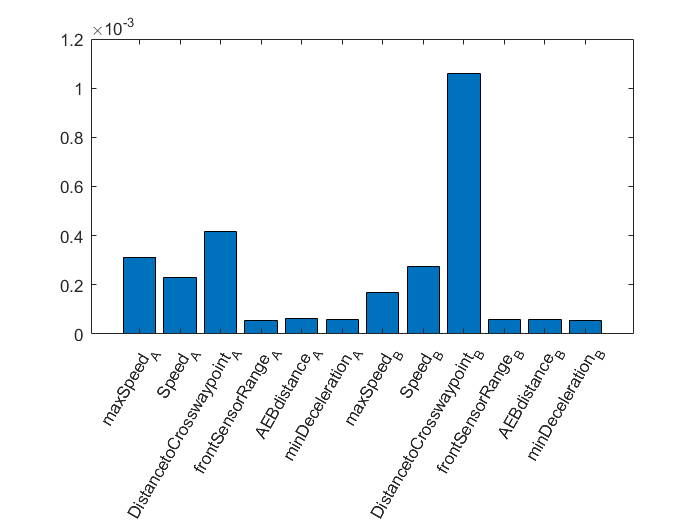

p0 = predictorImportance(Version3_1.ClassificationEnsemble);

%bar chart
bar(p0)
xticklabels(Data2.Properties.VariableNames(1:end-1))
xtickangle(60)

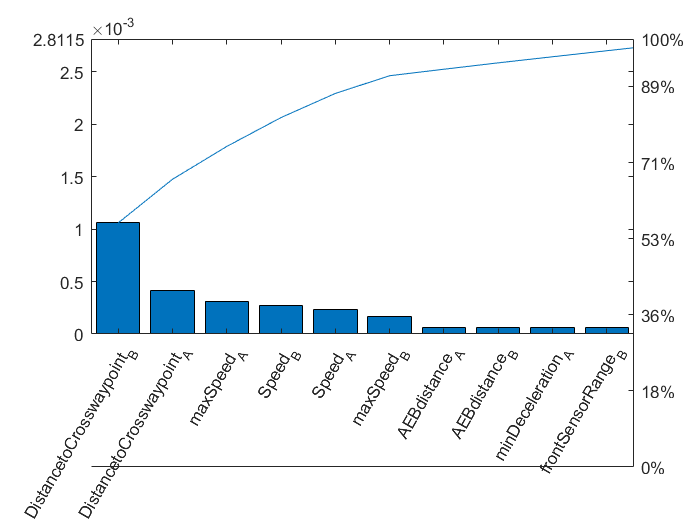


% pareto chart
pareto(p0,Data2.Properties.VariableNames(1:end-1))
xtickangle(60)